# mlx_cameraAntiAliasing

Illustrate the effect of the anti-aliasing filters.  This script compares blur and birefringent filters and lets you experiment with changing the f/# of the imaging optics.

Copyright Imageval Consulting, LLC, 2015

ieInit

## Image a high frequency orientation scene through f/2 optics

You can try using a larger f/# - say 8 - and you will see that in that case there is no real need for the anti-aliasing filter.  The image is blurred by the imaging optics, and then just blurred more by the filter.

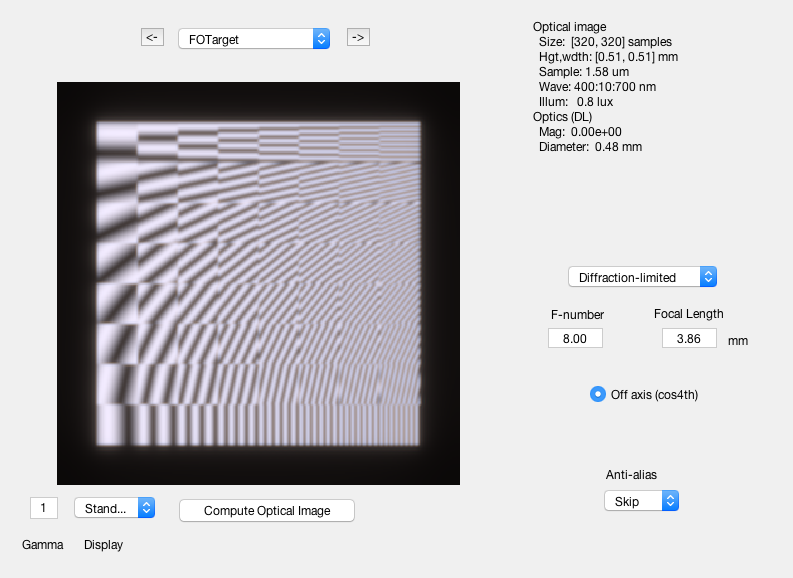

s = sceneCreate('freq orient',512);
s = sceneSet(s,'h fov',6);
oi = oiCreate;
oi = oiSet(oi,'optics fnumber',2);
oi = oiCompute(oi,s);
ieAddObject(oi); oiWindow;

## Create a 1.5 um pixel sensor and then image process it

Notice the color artifacts at the edges of the blocks and in the higher frequency portions of the image.

sensor = sensorCreate;
sensor = sensorSet(sensor,'pixel size constant fill factor',[1.5 1.5]*1e-6);
sensor = sensorSetSizeToFOV(sensor,5,s,oi);

sensor = sensorCompute(sensor,oi);
ip = ipCreate;

Interpolating display SPD for consistency with new wave.


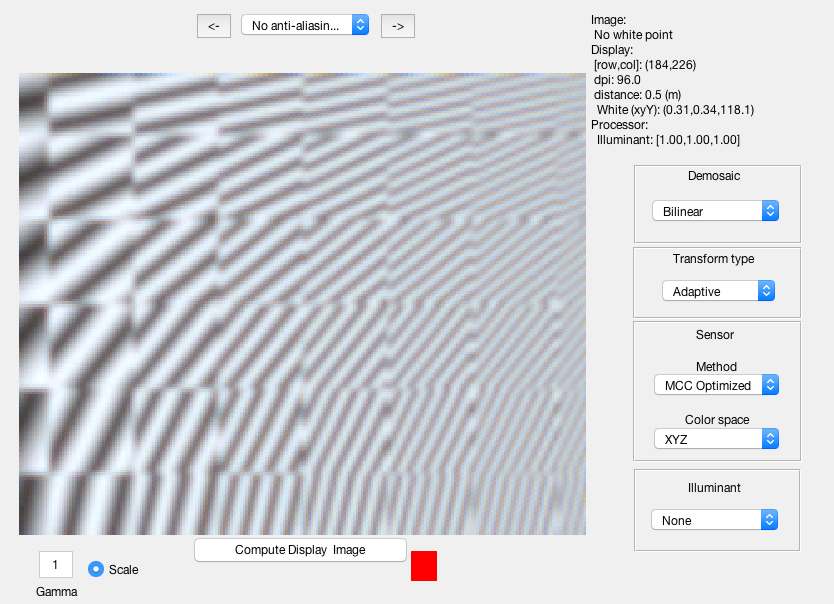

ip = ipCompute(ip,sensor);
ip = ipSet(ip,'name','No anti-aliasing filter');
ieAddObject(ip); ipWindow;

## Insert a blurring anti-aliasing filter into the optics and repeat

The color artifacts are reduced or eliminated. But the image has lower contrast (appears blurry).

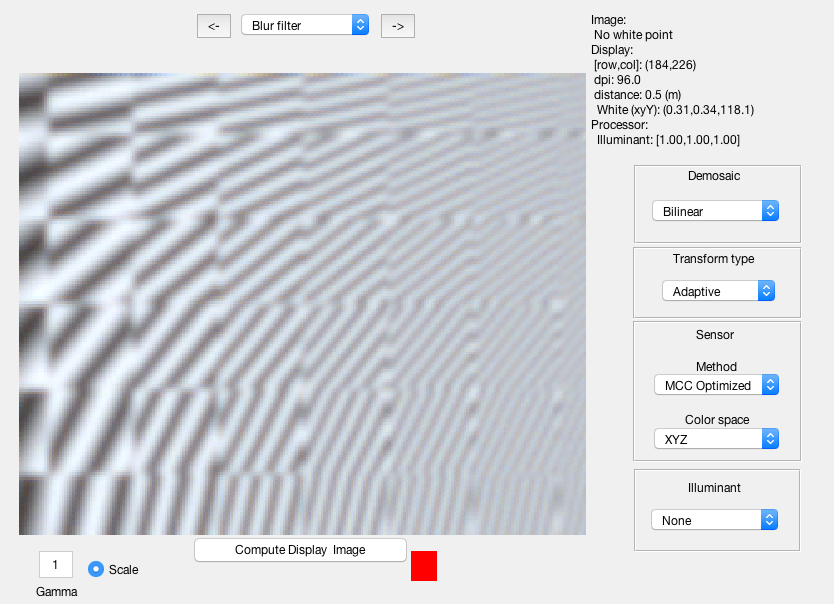

% Blur FWHM one pixel size
oi = oiSet(oi,'diffuser method','blur');
pSize = sensorGet(sensor,'pixel size');
oi = oiSet(oi,'diffuser blur', pSize(1));
oi     = oiCompute(oi,s);
sensor = sensorCompute(sensor,oi);
ip = ipCompute(ip,sensor);
ip = ipSet(ip,'name','Blur filter');
ieAddObject(ip); ipWindow;

## Use a birefringent anti-aliasing filter

A little sharper, but a little more color.

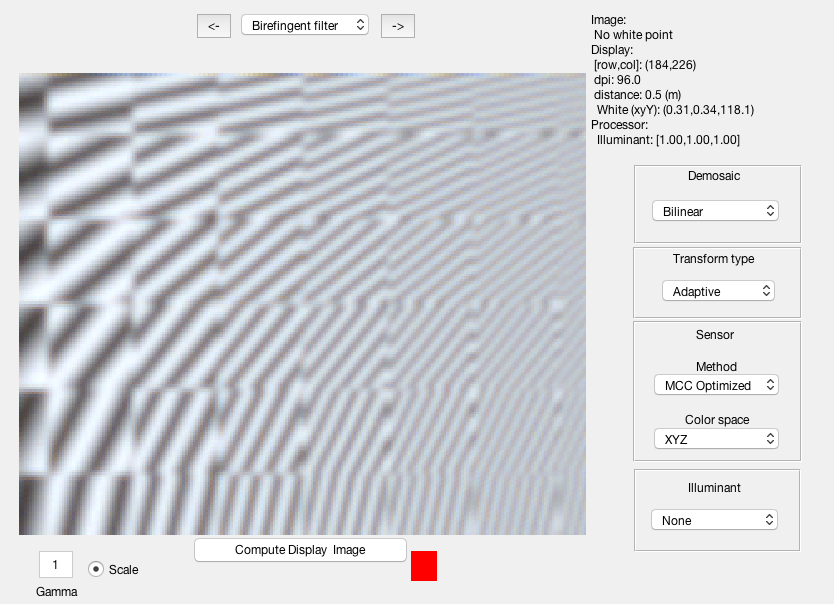

ieAddObject(sensor);   % Needed for birefringent computation
oi = oiSet(oi,'diffuser method','birefringent');
oi = oiCompute(oi,s);
sensor = sensorCompute(sensor,oi);
ip = ipCompute(ip,sensor);
ip = ipSet(ip,'name','Birefingent filter');
ieAddObject(ip); ipWindow;